## **ECS 174 Computer Vision, Spring 2020, Problem Set 0**

Cai Li     913432338

**Problem 1**

**2. Describe (in words where appropriate) the result of each of the following Matlab commands. **

a. Assign the variable x with a vector containing random permuted integars ranging from 1 to 50.

b. Create a 3 by 3 matrix and assign it to the variable a. Then return the second row as a vector to the variable b.

c. Create a 3 by 3 matrix and assign it to the variable a. Then melt the matrix a to a 1d vector containing all the elements of a and assign it to the variable b.

d. Create a 1d vector with 5 elements that are randomly selected based on a standard normal distribution and assign it to the variable f. Find the f elements which are larger than 0 and return them as a 1d vector to the variable g.

e. Create a 6 element 1d vector with all the elements being 0.5 and assign it to the variable x. Then create a vector with same number of elements as x with all the elements being 0.5 and assign it to the variable y. Sum the x an y elementwise and assign it to the variable z.

f. Crate a 4 element vector [1,2,3,4] to the variable a. Reverse the order of the vector a and assign it to the variable b.

**3. Write a few lines of code to do each of the following.**

**a. Use **`rand `**to write a function that returns the roll of a six-sided die.**

% test
for i = 1:5
    disp(rollDie());
end

     3



     2



     6



     2



     2



% function val = rollDie()
%     val = ceil(rand(1) * 6);
% end

**b. Let **`y `**be the vector: **`y = [1 2 3 4 5 6]`**. Use the **`reshape `**command to form a new matrix Z that looks like this: Z = **$\left\lbrack \begin{array}{c}
1 & 3 & 5\\
2 & 4 & 6
\end{array}\right\rbrack$

y = 1:6;
Z = reshape(y,2,3);
disp(Z);

     1     3     5
     2     4     6



**c. Use the **`min `**and **`find `**functions to set **`x `**to the minimum value that occurs in Z (above), and set **`r `**to the row it occurs in and **`c `**to the column it occurs in. **

x = min(Z(:));
[row, col] = find(Z == x);
r = Z(row, :);
c = Z(:, col);
disp(x); disp(r); disp(c);

     1

     1     3     5

     1
     2



**d. Let **`v `**be the vector: **`v = [2 8 3 2 1 8 1 8]`**. Set a new variable **`x `**to be the number of 8’s in the vector **`v`**.**

v = [2, 8, 3, 2, 1, 8, 1, 8];
x = numel(find(v == 8));
disp(x);

     3



**4. Create any 100 x 100 matrix A (not all constant). Save A in a .mat file called PS0_A.mat and submit it. Write a script which loads PS0_A.mat and performs each of the following actions on A. Name it PS0_Q1.m and submit it. Try to avoid using for loops.**

A = rand(100);
save('PS0_A.mat', 'A');
temp = load('PS0_A.mat', 'A');
A = temp.A;

**a. Plot a figure of all the intensities in A, sorted in decreasing value. Provide the plot in your answer sheet. (Note, in this case we don’t care about the 2D structure of A, we only want to sort all the intensities in one list.)**

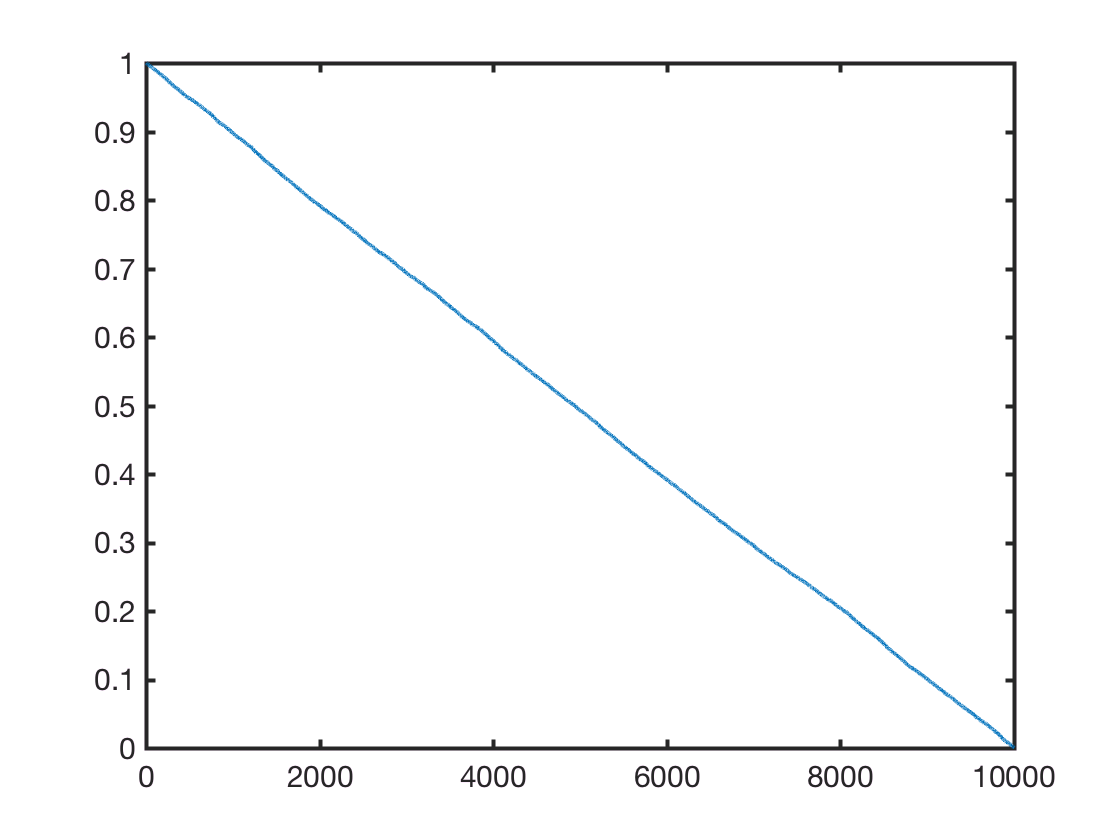

figure;
plot(sort(A(:), 'descend'), 'lineWidth', 2);
set(gca, 'fontSize', 15, 'lineWidth', 2);

**b. Display a histogram of A’s intensities with 10 bins. Provide the plot in your answer sheet.**

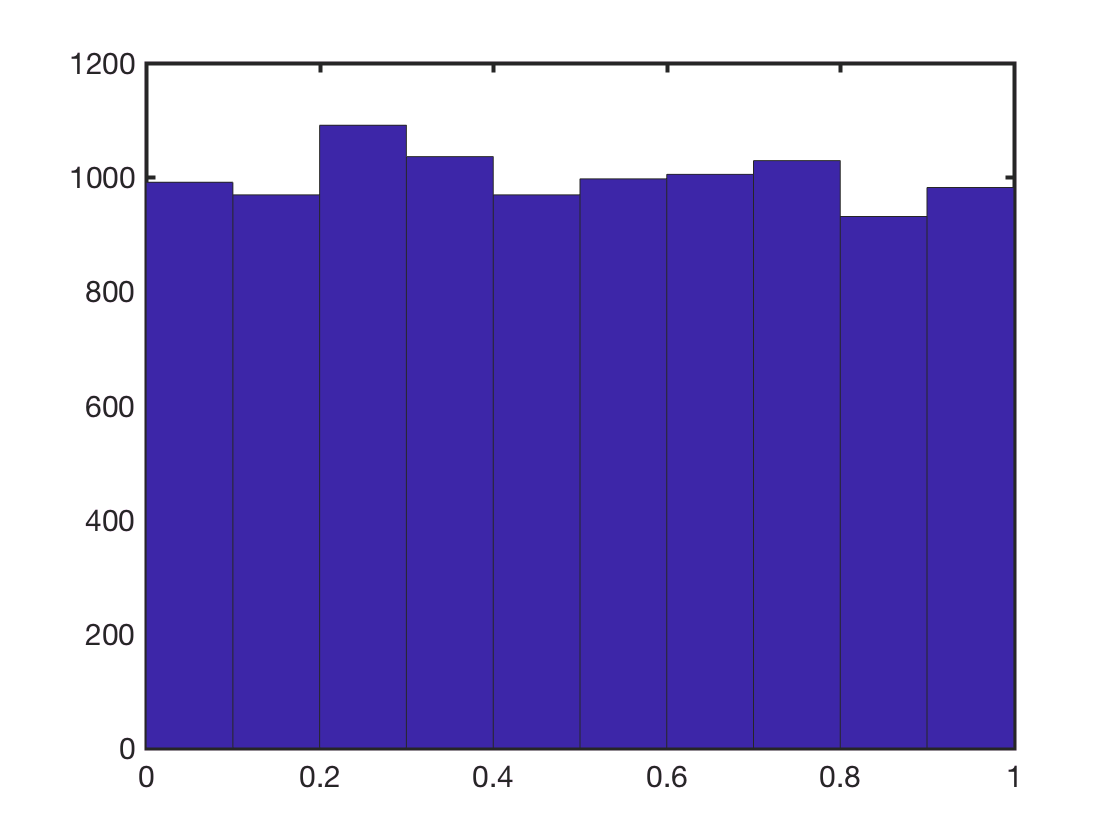

figure;
hist(A(:), 10, 'FaceColor', 'g', 'lineWidth', 2);
set(gca, 'fontsize', 15, 'lineWidth', 2);

**c. Create a new matrix Z that consists of the bottom left quadrant of A. Display Z as an image in your answer sheet using **`imagesc`**.**

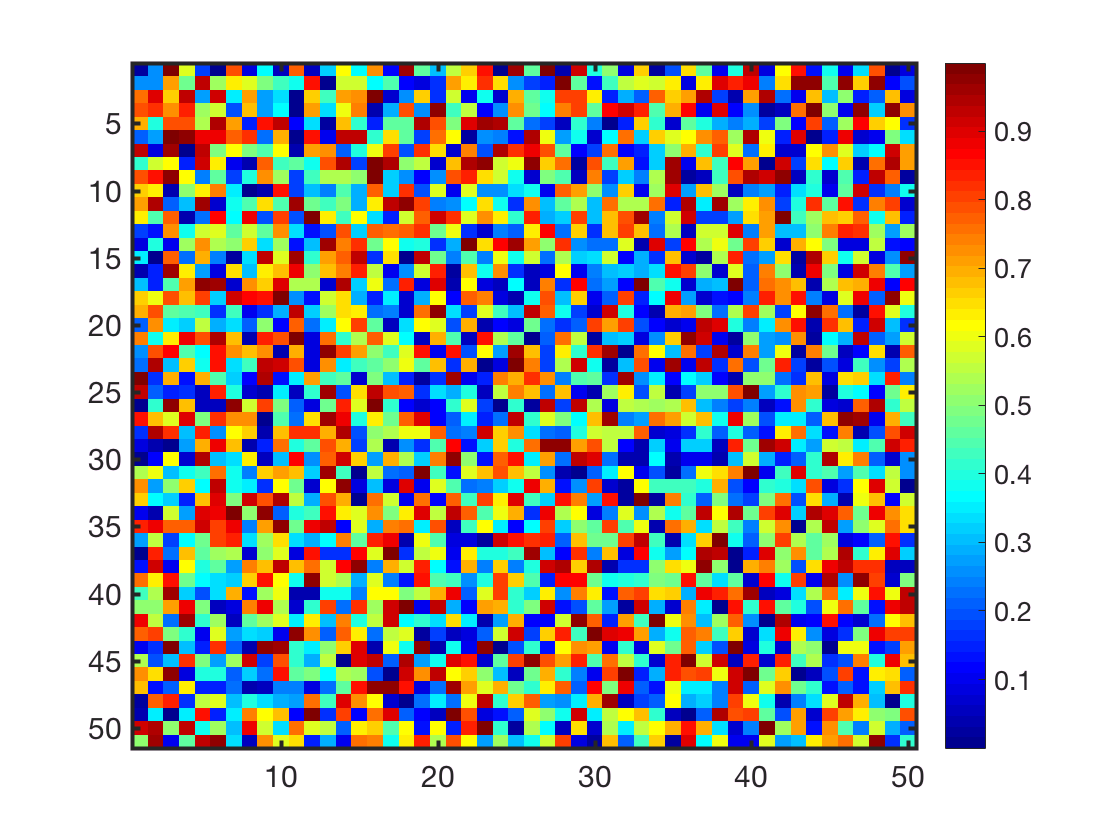

Z = A(floor(size(A, 1)/2):end, 1:floor(size(A,2)/2));
figure;
imagesc(Z);
colormap jet;
set(gca, 'fontsize', 15, 'linewidth', 2);
colorbar;

**d. Generate a new image W, which is the same as A, but with A’s mean intensity value subtracted from each pixel. Display W as an image in your answer sheet using **`imagesc`**.**

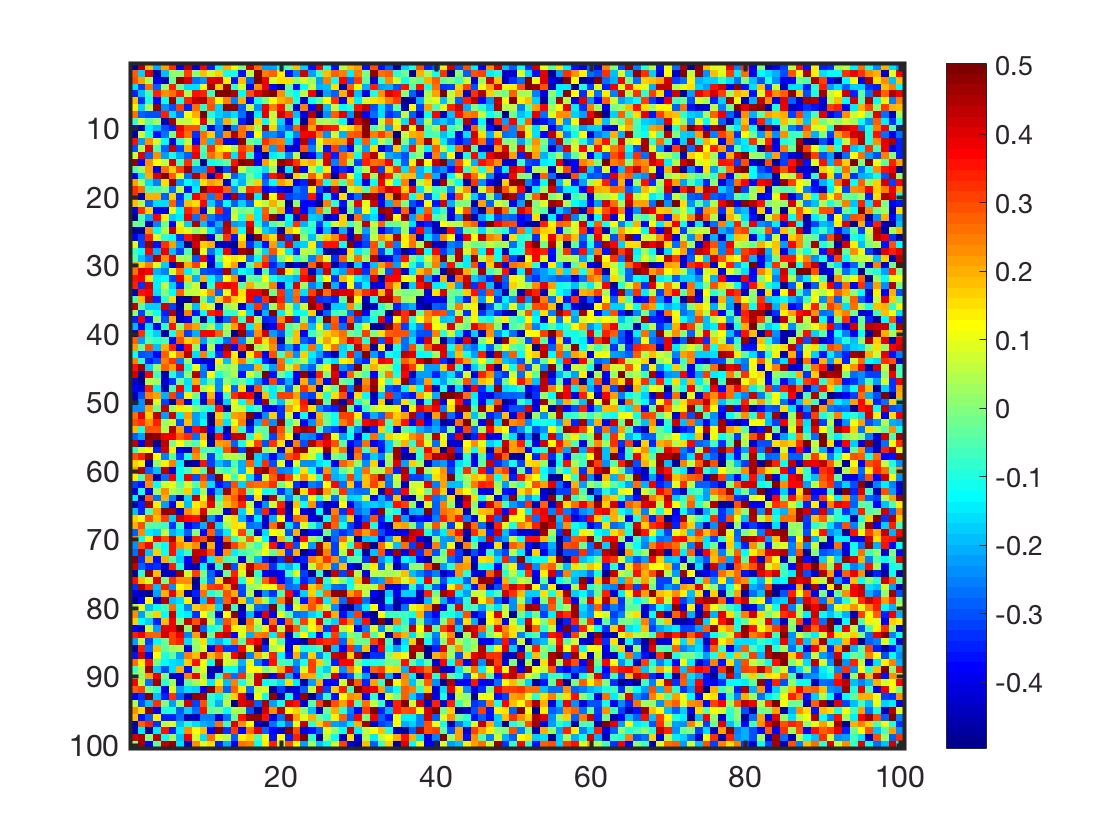

W = A - mean(A(:));
figure;
imagesc(W);
set(gca, 'fontsize', 15, 'linewidth', 2);
colormap jet;
colorbar;

**e. Create and display a new matrix Y that represents a color image with the same size as A, but with 3 channels to represent R G and B values. Set the values of Y to be red (i.e., R = 255, G = 0, B = 0) wherever the intensity in A is greater than a threshold **`t `**= the mean  intensity of A, and black (i.e., R = 0, G = 0, B = 0) everywhere else. Plot Y using **`imshow`**.**

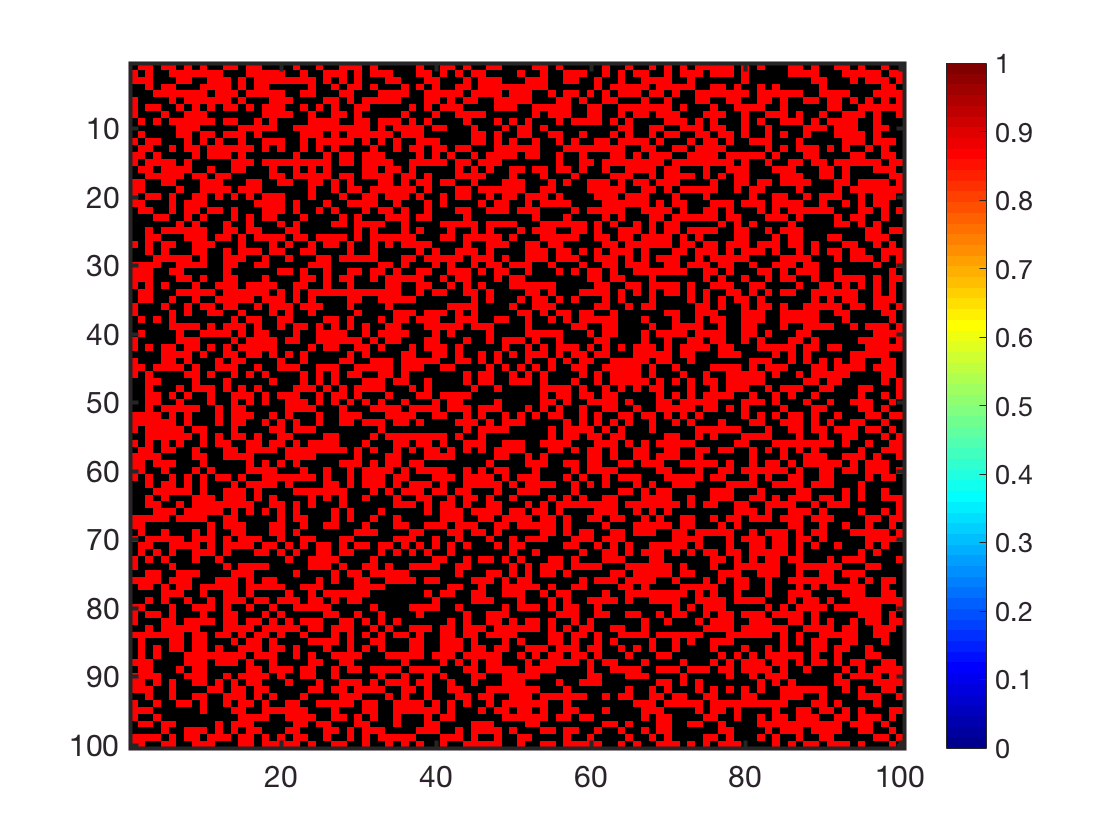

Y = zeros(size(A, 1), size(A, 2), 3);
t = mean(A(:));
Y = Y + cat(3, (A > t) * 255, zeros(size(A)), zeros(size(A)));
figure;
imagesc(Y);
set(gca, 'fontsize', 15, 'linewidth', 2);
colormap jet;
colorbar;

**Problem 2**

The transformation script is included in the current folder. An example image 'peppers' was used as a demonstration. The results were shown below: